#### Relation between DDM starting point and SDT parameters

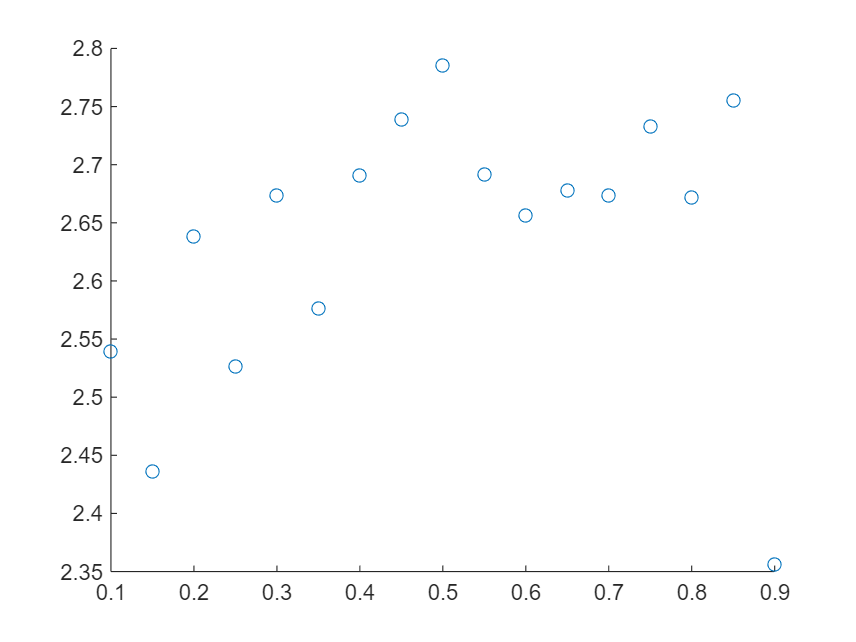

clear all
a = 2; % Boundary separation
v = 1.1; % Mean drift rate
w = [.1:.05:.9]; % Relative starting point
dt = 1/60; % Sampling rate

ntrials = 1000; % Number of simulated trials
% Initialize  RT and Response vectors
rt = nan(ntrials,1);
hits = nan(length(w),1);
fa = nan(length(w),1);
for wx = 1:length(w)
    resp = false(ntrials,1);
    for idx = 1:ntrials
        y = a.*w(wx);
        x= 0;
        goon = true;
        while goon
            y = [y y(end) + normrnd(v*dt, sqrt(dt))];
            x = [x x(end)+dt];
            if y(end)<0 || y(end)>a
                rt(idx) = x(end);
                resp(idx) = y(end)>a;
                goon = false;
            end
        end
    end
    hits(wx) = sum(resp)/ntrials;
    resp = false(ntrials,1);
    for idx = 1:ntrials
        y = a.*w(wx);
        x= 0;
        goon = true;
        while goon
            y = [y y(end) + normrnd(-v*dt, sqrt(dt))];
            x = [x x(end)+dt];
            if y(end)<0 || y(end)>a
                rt(idx) = x(end);
                resp(idx) = y(end)>a;
                goon = false;
            end
        end
    end
    fa(wx) = sum(resp)/ntrials;
end

zHits = norminv(hits);
zFA = norminv(fa);
dPrime = zHits-zFA;
c = - (zHits+zFA)/2;
figure, scatter(w,dPrime)

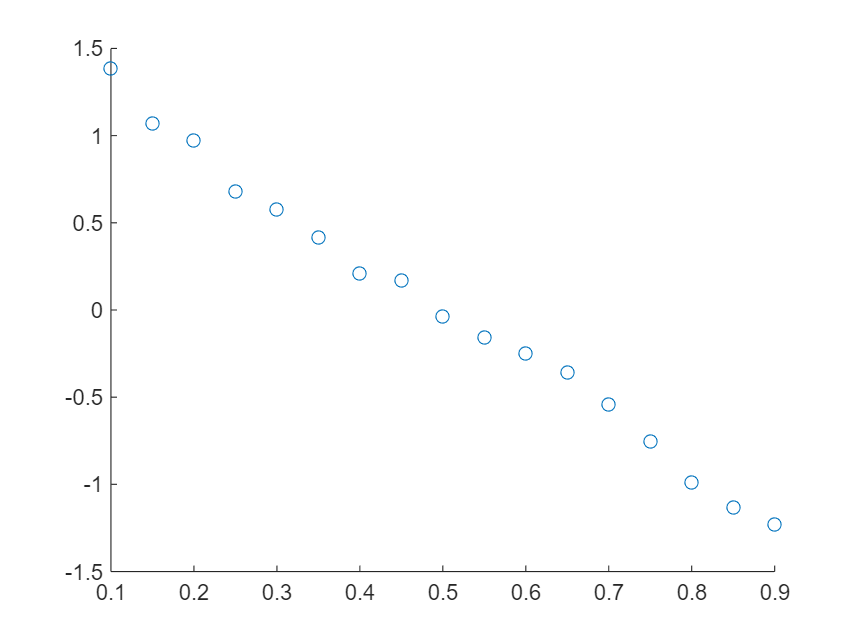

figure, scatter(w,c)

#### Relation between DDM drift rate and SDT parameters

clear all
a = 2; % Boundary separation
v_all = [1:.05:2]; % Mean drift rate
w = .5; % Relative starting point
dt = 1/60; % Sampling rate

ntrials = 1000; % Number of simulated trials
% Initialize  RT and Response vectors
rt = nan(ntrials,1);
hits = nan(length(w),1);
fa = nan(length(w),1);
for vx = 1:length(v_all)
v= v_all(vx)
    resp = false(ntrials,1);
    for idx = 1:ntrials
        y = a.*w;
        x= 0;
        goon = true;
        while goon
            y = [y y(end) + normrnd(v*dt, sqrt(dt))];
            x = [x x(end)+dt];
            if y(end)<0 || y(end)>a
                rt(idx) = x(end);
                resp(idx) = y(end)>a;
                goon = false;
            end
        end
    end
    hits(vx) = sum(resp)/ntrials;
    resp = false(ntrials,1);
    for idx = 1:ntrials
        y = a.*w;
        x= 0;
        goon = true;
        while goon
            y = [y y(end) + normrnd(-v*dt, sqrt(dt))];
            x = [x x(end)+dt];
            if y(end)<0 || y(end)>a
                rt(idx) = x(end);
                resp(idx) = y(end)>a;
                goon = false;
            end
        end
    end
    fa(vx) = sum(resp)/ntrials;
end

v = 1

v = 1.0500

v = 1.1000

v = 1.1500

v = 1.2000

v = 1.2500

v = 1.3000

v = 1.3500

v = 1.4000

v = 1.4500

v = 1.5000

v = 1.5500

v = 1.6000

v = 1.6500

v = 1.7000

v = 1.7500

v = 1.8000

v = 1.8500

v = 1.9000

v = 1.9500

v = 2

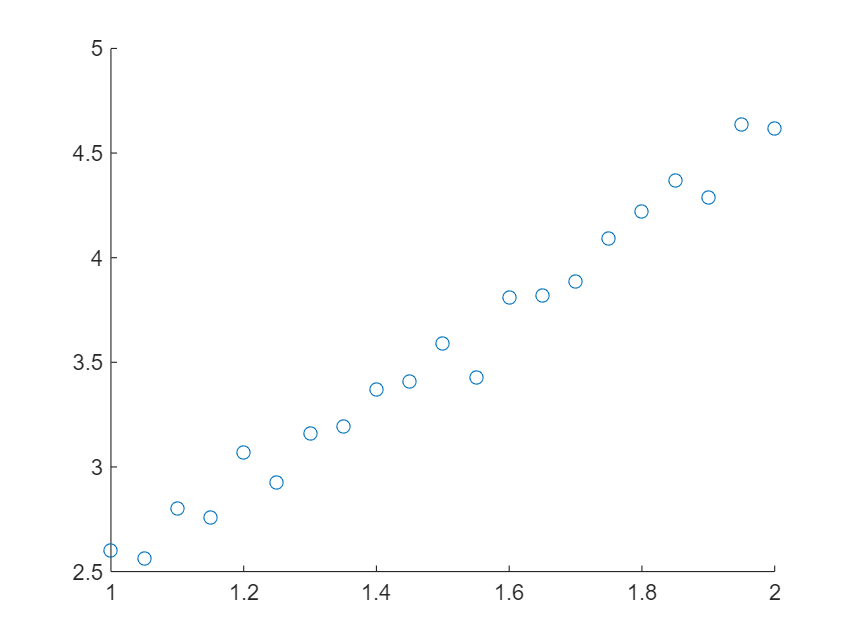


zHits = norminv(hits);
zFA = norminv(fa);
dPrime = zHits-zFA;
c = - (zHits+zFA)/2;
figure, scatter(v_all,dPrime)

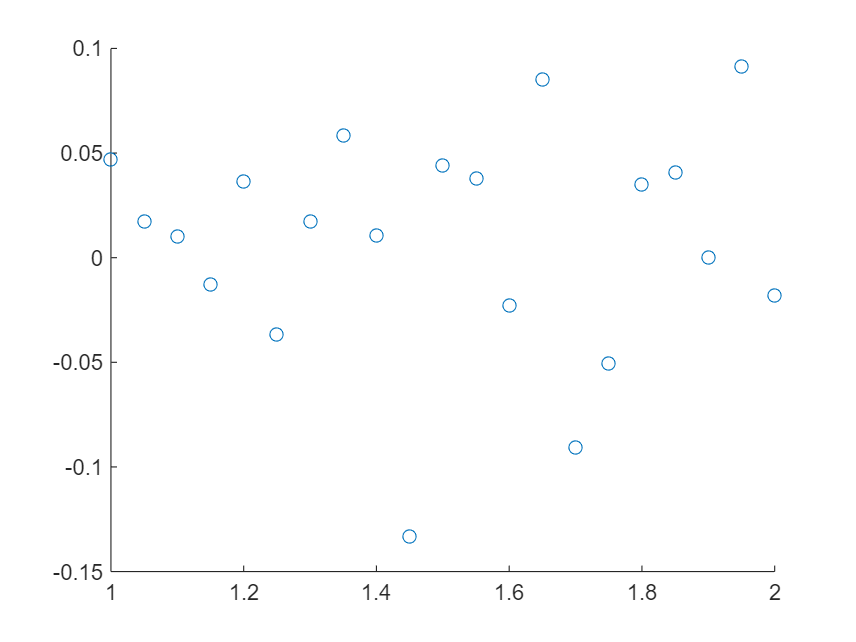

figure, scatter(v_all,c)